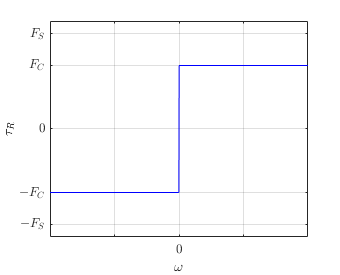

clear
close all


% Function parameters
F_C = 1;
F_S = 1.5;
nu_S = 1;
delta_S = 1;
F_v = 0.03;


% Plot settings
saveData = 1;

pathOut = 'plot_data/friction_models';

ylimit = 1.7;
xlimit = 10;

plotWidth = 730;
plotHeight = 275;

plotWidth = (plotWidth - 50) / 2;

xticksVec = [-xlimit, -0.5*xlimit, 0, 0.5*xlimit, xlimit];
xticksString = {'' '' '$0$' '' ''};
yticksVec = [-F_S, -F_C, 0, F_C, F_S];
yticksString = {'$-F_S$' '$-F_C$' '$0$' '$F_C$' '$F_S$'};

% Change to Latex interpreter
listFactory = fieldnames(get(groot,'factory'));
idxInterpreter = find(contains(listFactory,'Interpreter'));
for k = 1:length(idxInterpreter)
    defaultName = strrep(listFactory{idxInterpreter(k)},'factory','default');
    set(groot, defaultName,'latex');
end

% Create Output path
if ~exist(pathOut,'dir') && saveData
    mkdir(pathOut);
end

% Functions
t = (-xlimit:0.01:xlimit)';

coulomb = sign(t) .* F_C;
stiction = [-F_S; F_S];
viscous = sign(t) .* (F_C + F_v.*abs(t));
stribeck = sign(t) .* (F_C + (F_S-F_C).*exp(-(abs(t)./nu_S).^delta_S) + F_v.*abs(t));

% Coulomb Friction
fCoulomb = figure;

plot(t,coulomb,'b-')

xlim([-xlimit xlimit])
ylim([-ylimit ylimit])
xlabel('$\omega$')
ylabel('$\tau_R$')
xticks(xticksVec)
xticklabels(xticksString)
yticks(yticksVec)
yticklabels(yticksString)
grid on
box on

fCoulomb.Position = [680 558 plotWidth plotHeight];

if saveData
    fileName = strcat(pathOut,'/coulomb_friction.pdf');
    exportgraphics(fCoulomb,fileName,'Append',true);
end

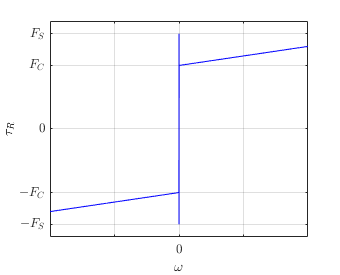



% Static and Viscous Friction
fViscous = figure;

hold on
plot(t,viscous,'b-')
plot([0; 0],stiction,'b-')
hold off

xlim([-xlimit xlimit])
ylim([-ylimit ylimit])
xlabel('$\omega$')
ylabel('$\tau_R$')
xticks(xticksVec)
xticklabels(xticksString)
yticks(yticksVec)
yticklabels(yticksString)
grid on
box on

fViscous.Position = [680 558 plotWidth plotHeight];

if saveData
    fileName = strcat(pathOut,'/viscous_friction.pdf');
    exportgraphics(fViscous,fileName,'Append',true);
end

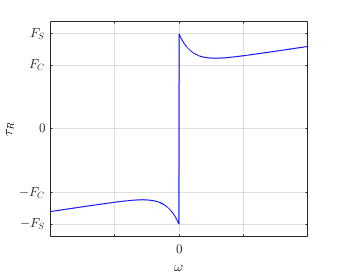


% Stribeck Friction
fStribeck = figure;

plot(t,stribeck,'b-')

xlim([-xlimit xlimit])
ylim([-ylimit ylimit])
xlabel('$\omega$')
ylabel('$\tau_R$')
xticks(xticksVec)
xticklabels(xticksString)
yticks(yticksVec)
yticklabels(yticksString)
grid on
box on

fStribeck.Position = [680 558 plotWidth plotHeight];

if saveData
    fileName = strcat(pathOut,'/stribeck_friction.pdf');
    exportgraphics(fStribeck,fileName,'Append',true);
end